clear all

tspan = 2014:0.1:2200;
all_results = simESM_w_soc(100, tspan);

test:
   100

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

Elapsed time is 9.067364 seconds.


all_results

all_results = struct with fields:
          xvals: [1861×100 double]
           catm: [1861×100 double]
            coc: [1861×100 double]
           cveg: [1861×100 double]
            cso: [1861×100 double]
              T: [1861×100 double]
        pre2014: [2141×7 double]
    blineParams: [1861×6 double]


temperature_vals = all_results.T;
bline_params_results = all_results.blineParams;

median_vals = quantile(temperature_vals', 0.5);
bot_five    = quantile(temperature_vals', 0.05);
top_five    = quantile(temperature_vals', 0.95);

plot(all_results.pre2014(:,1), all_results.pre2014(:,end))
%plot(test_1751to2014(:,1), test_1751to2014(:,end))
hold on
%plot(tspan, avg_(:,end))
xlim([1900,2200])
ylim([0,5])
size(temperature_vals)

ans =         1861         100


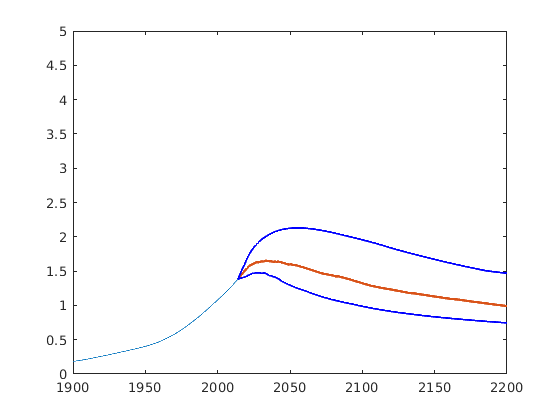


%plot(tspan, bline_params_results(:,end))
plot(tspan, median_vals, 'LineWidth', 2)
plot(tspan, top_five, 'LineWidth', 1.5, 'Color','b')
alpha(0.15);
plot(tspan, bot_five, 'LineWidth', 1.5, 'Color','b')

alpha(0.15);

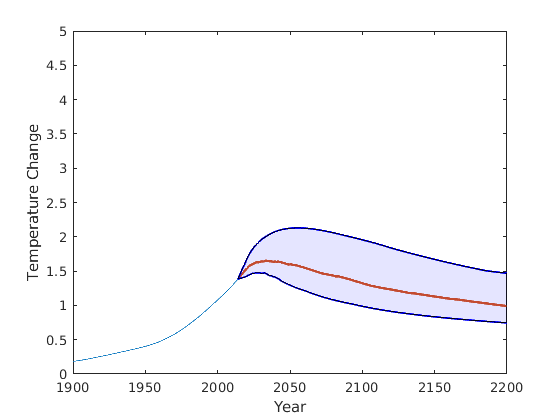

x2 = [tspan, fliplr(tspan)];
inBetween = [bot_five, fliplr(top_five)];
fill(x2, inBetween, 'b');
alpha(0.1);
xlabel('Year')
ylabel('Temperature Change')


%{

    x0    = 0.05;
    kappa = 0.2;
    delta = 0.5;
    beta  = 0.5;
    t_f   = 50;
    f_max = 6;
%}

ctst

res_ = sensiAna;
res_

res_ = struct with fields:
            maxT: [1×1 struct]
    paramsVaried: [1×1 struct]


res_.maxT

ans = struct with fields:
      kappa: [3.5818 2.8032 2.3064]
      delta: [2.6468 2.8032 3.0183]
       beta: [2.5948 2.8032 3.0790]
         s_: [2.7691 2.8032 2.8244]
         x0: [2.7953 2.8032 2.8165]
      C_at0: [2.7921 2.8032 2.8147]
      C_oc0: [2.8043 2.8032 2.8022]
     C_veg0: [2.7934 2.8032 2.8217]
      C_so0: [2.8132 2.8032 2.7965]
        k_p: [2.7887 2.8032 2.9286]
        k_c: [2.8072 2.8032 2.7993]
        k_M: [2.8621 2.8032 2.7704]
        k_r: [2.9352 2.8032 2.7944]
        E_a: [2.7883 2.8032 2.9002]
       k_sr: [2.9553 2.8032 2.8234]
        k_t: [2.8249 2.8032 2.8057]
          c: [2.7619 2.8032 2.8422]
          A: [2.8339 2.8032 2.7884]
          S: [3.0817 2.8032 2.8844]
    tao_CH4: [2.8004 2.8032 2.8061]
        P_0: [2.8032 2.8032 2.8032]
        F_0: [2.8208 2.8032 2.7873]
        chi: [2.8694 2.8032 2.7558]
       zeta: [2.8001 2.8032 2.8063]
      f_max: [3.1992 2.8032 2.5796]
      omega: [2.9892 2.8032 2.7623]
        T_c: [2.6810 2.8032 2.9319]
  

namesNice = [ "t_f", "\kappa", ...
"f_{max}", "\beta", "\delta", "S", "T_c", "\omega", ...
"k_{sr}", "k_r", "k_p", "\chi", "E_a", "k_M", ...
"c", "s", "A", "f_0", "C_{veg0}", "k_t", ...
"C_{at0}", "x0", "C_{so0}", "k_c", "\zeta", ...
"\tau(CH4)", "C_{oc0}", "P_0"];
sortedNamesNice = categorical([ "t_f", "\kappa", ...
"f_{max}", "\beta", "\delta", "S", "T_c", "\omega", ...
"k_{sr}", "k_r", "k_p", "\chi", "E_a", "k_M", ...
"c", "s", "A", "f_0", "C_{veg0}", "k_t", ...
"C_{at0}", "x0", "C_{so0}", "k_c", "\zeta", ...
"\tau(CH4)", "C_{oc0}", "P_0"]);

give2barh = [];
fldnames  = fieldnames(res_.maxT);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxT.(fldname_)];
end

ctst = categorical(fldnames)'

ctst = 1×37 categorical array
     homophily      alpha_P0      alpha_P1      alpha_R0      omega_R      omega_P      k_R      k_P      c_R      c_P      delta      s_      xP0      xR0      C_at0      C_oc0      C_veg0      C_so0      k_p      k_c      k_M      k_r      E_a      k_sr      k_t      c      A      S      tao_CH4      P_0      F_0      chi      zeta      f_max      omega      T_c      t_f 


% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
[A,sortIdx] = sort(sizeBar,'descend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(fldnames(sortIdx))';
sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));

Undefined function or variable 'sortedNamesNice'.

mn1 = mean(give2barh);
mn1 = mn1(2); % grab the average of the baseline values.
%barh(ctst, give2barh, 'BaseValue',mn1) % prob doesn't work in livescript

%{
descriptions = struct();
descriptions.t_f = "Time horizon of temperature projection";
descriptions.kappa = "Social learning rate";
descriptions.f_max = "Maximum of warming cost function"
descriptions.beta = "Net cost of mitigation"
descriptions.delta = "Strength of social norms", ...
descriptions.k_sr = "Soil respiration rate", ...
descriptions.S = "Solar flux", ...
descriptions.T_c = "Critical temperature of warming cost function", ... % Tc
"Nonlinearity of warming cost function", ... % omega    
    "Plant respiration rate", ... % K_r
    "Photosynthesis rate constant", ... % k_p
    "Plant respiration activation energy", ... % E_a
    "Half-saturation point for photosynthesis", ... % k_M
    "Characteristic CO_2 solubility", ... %chi
    ];
%}

barh(ctst, give2barh)

ctst2 = categorical({'helloe', 'goodbye'});
tst2  = [20,40;60,80];

barh(ctst2, tst2)

res_.paramsVaried